# Experiment object creation for analysis

#### Creat aud_ephys experiment object (Including all unprocessed data: Pathways, input channels, facemap whisking analysis, running, mic, spk, sorted spikes and metadata, condition ephocs, evoked events, aligned cam frames)

Choose parameters file for exp

clear 
clc
close all

cd /home/ben/Z/Parameters_files/FVB/ % optional 
[file,path] = uigetfile('*.m');
cd(path)
%run(file)

Create an initial object

experiment = auditory_ephys_exp(file)

time_to_discard =         1977        1986


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: []
              Conditions: []
                    Cams: []
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
                   PSTHs: []
                   sound: []
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []
            analysisType: []
            time2discard: [1977 1986]
                     SDF: []


Choose which additional data to add to the experiment object based on the type of experiment (comment and uncomment as necessery)

% Condition times
experiment.Conditions = experiment.getConditionsTimes

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: []
              Conditions: [1×1 struct]
                    Cams: []
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
                   PSTHs: []
                   sound: []
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []
            analysisType: []
            time2discard: [1977 1986]
                     SDF: []


% Units
experiment.Units = sorted_from_phy(experiment.Pathways.sorting)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: []
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
                   PSTHs: []
                   sound: []
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []
            analysisType: []
            time2discard: [1977 1986]
                     SDF: []


% cameras sync
% whisking camera sync
experiment.Cams.whisking = experiment.syncCamera(1)

Choose csv file for the whisking camera


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
                   PSTHs: []
                   sound: []
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []
            analysisType: []
            time2discard: [1977 1986]
                     SDF: []


% face camera sync
% experiment.Cams.whisking = experiment.syncCamera(2)

% evoked events based on speaker data
experiment.evokedEvents = experiment.getEvoked

Analog data channels

cd([experiment.Pathways.exp,'/experiment1/recording1'])
data = load_open_ephys_binary('structure.oebin','continuous',1,'mmap');
experiment.sound.full = data.Data.Data.mapped(32+experiment.analog_channels.mic,:)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: []
                   PSTHs: []
                   sound: [1×1 struct]
                 running: []
            evokedEvents: []
         conditionVector: []
                Whisking: []
               timeStamp: []
            analysisType: []
            time2discard: [1977 1986]
                     SDF: []


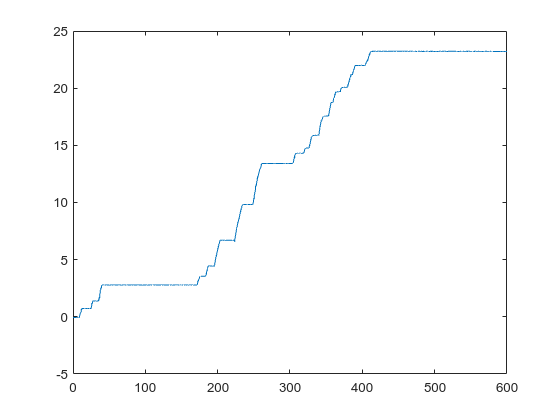

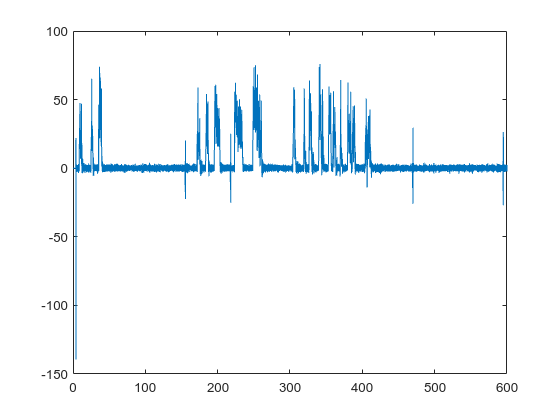

experiment.running = encoder2speed(data.Data.Data.mapped(32+experiment.analog_channels.encoder,:),0.065);

clear data

Varify conditions channels and what ever

figure; plot([1:length(experiment.sound.full)]/30000,experiment.sound.full)

xline(experiment.Conditions.all_changes/30000)


conditionDiff = diff(experiment.Conditions.all_changes)/30000

% % for exp FVB 108_986
% experiment.Conditions.all_changes = [experiment.Conditions.all_changes(1:4);12251365;experiment.Conditions.all_changes(5:end)];
% experiment.Conditions.condition_classification = [experiment.Conditions.condition_classification(1:4);1;experiment.Conditions.condition_classification(5:end)];

Save experiment 

cd /media/ben/'Extreme SSD'/analysisData/
save([experiment.experiment_ID,'.mat'],'experiment','-mat')

experiment.experiment_ID

clearvars -except experiment
clc
close all

Load experiment

% cd /media/ben/'Extreme SSD'/analysisData/
% load('FVB111_715.mat','experiment')

## Processes data

Identify whisking epochs and divided into two types

Load whisking vector, and chossing the appropriate one for analysis

cd(experiment.Pathways.main)
[file,path] = uigetfile('*.mat');
load([path,file],'motion_1','motSVD_1');

figure;plot(motion_1)

figure; plot(abs(motSVD_1(:,2)))

whiskingData = motSVD_1(:,2)';

%whiskingData = wdenoise(double(whiskingData),5)

%figure; plot(whiskingData)

clear motSVD_1 motion_1


%figure; plot(whiskingData)

Filter and smooth data to identify threshold

[b,a] = butter(3,[10,50]/200,'bandpass')
whisking_filtered = filtfilt(b,a,double(whiskingData))
figure; plot(whisking_filtered)

whisking_smoothed = smoothdata(abs(whisking_filtered),"movmean","SmoothingFactor",0.5)

% Load experiment object
cd /media/ben/'Extreme SSD'/analysisData/ % optional 
[file,path] = uigetfile('*.mat');
cd(path)
load(file)

whisking_smoothed = experiment.Whisking.smoothed';

% figure;
% plot([1:length(whisking_filtered)]/400/60,abs(whisking_filtered))
% hold on

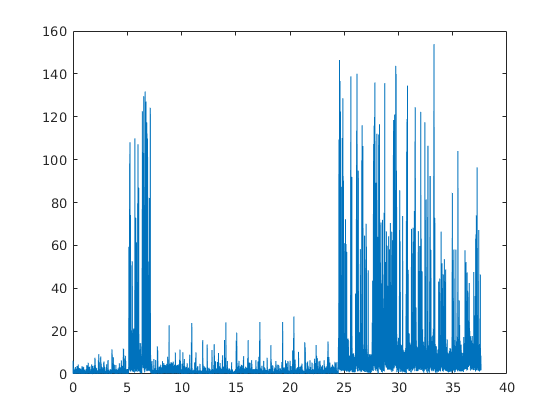

plot([1:length(whisking_smoothed)]/400/60,whisking_smoothed)

Identify whisking epochs

thr = 1.5

all_above = find(whisking_smoothed > thr)
all_below = find(whisking_smoothed <= thr)

start_epoch = intersect(all_above,all_below+1)

endEpoch = intersect(all_above,all_below-1)


if endEpoch(1) < start_epoch(1)
    endEpoch(1) = []
end

jj = endEpoch(1:end-1) - start_epoch(2:end);

 jjk = jj > -300

 endEpoch(jjk) = []
 start_epoch([false,jjk]) = []

if length(start_epoch) > length(endEpoch)
    endEpoch = [endEpoch,length(whisking_smoothed)]
end

figure
plot([1:length(whisking_smoothed)]/400,whisking_smoothed)
xline(start_epoch/400)
xline(endEpoch/400,'r')

divide epochs to short epochs and long continuous whisking

epochLength = endEpoch-start_epoch

extremeShortEpochs = epochLength < 20

start_epoch(extremeShortEpochs) = [];
endEpoch(extremeShortEpochs) = [];
epochLength(extremeShortEpochs) = [];

clear longEpoch
longEpoch(:,1) = start_epoch(epochLength > 200)
longEpoch(:,2) = endEpoch(epochLength > 200)

clear shortEpoch
shortEpoch(:,1) = start_epoch(epochLength <= 200)
shortEpoch(:,2) = endEpoch(epochLength <= 200)

varify epochs

figure
plot([1:length(whisking_smoothed)]/400,whisking_smoothed)
hold on
yupper = 100
y = [0 0 yupper yupper]
for i = 1:length(longEpoch)
    x = [longEpoch(i,1)/400,longEpoch(i,2)/400,longEpoch(i,2)/400,longEpoch(i,1)/400]
    fill(x,y,'r','FaceAlpha',0.3)
end
for i = 1:length(shortEpoch)
    x = [shortEpoch(i,1)/400,shortEpoch(i,2)/400,shortEpoch(i,2)/400,shortEpoch(i,1)/400]
    fill(x,y,'b','FaceAlpha',0.3)
end

experiment.Whisking.long = longEpoch

experiment.Whisking.short = shortEpoch

experiment.Whisking.smoothed = whisking_smoothed;
experiment.Whisking.Raw = whiskingData

Save experiment 

cd /media/ben/'Extreme SSD'/analysisData/
save([experiment.experiment_ID,'.mat'],'experiment','-v7.3')

experiment.experiment_ID

clearvars -except experiment
clc
close all

Load experiment

% cd /media/ben/'Extreme SSD'/analysisData/
% load('FVB110_600.mat','experiment')

Identify sound events (Only when sound is clean enough through all conditions)

%figure; plot(experiment.sound.full)
% crosscorrelation between sound and 

filter

[b,a] = butter(3,[800]/15000,'high')
sound_filtered = filtfilt(b,a,double(experiment.sound.full))
figure; plot(sound_filtered)

sound_smoothed = smoothdata(abs(sound_filtered),"movmean","SmoothingFactor",0.5)

figure;
plot([1:length(sound_filtered)]/30000/60,abs(sound_filtered))
hold on
plot([1:length(sound_filtered)]/30000/60,sound_smoothed)

th = 60

sound_above = find(sound_smoothed > th)
sound_below = find(sound_smoothed <= th)

startSound = intersect(sound_above,sound_below+1)
endSound = intersect(sound_above,sound_below-1)

jj = endSound(1:end-1) - startSound(2:end);
jjk = jj > -600

endSound(jjk) = []
 startSound([false,jjk]) = []

startPlot = 600
endPlot = 800

figure;
plot([startPlot*30000:endPlot*30000]/30000,sound_smoothed(startPlot*30000:endPlot*30000))
startSoundPart = startSound > startPlot*30000 & startSound < endPlot*30000;
endSoundPart = endSound > startPlot*30000 & endSound < endPlot*30000;
xline(startSound(startSoundPart)/30000)
xline(endSound(endSoundPart)/30000,'r')

experiment.sound_events = [startSound;endSound]'

experiment.sound.smoothed = sound_smoothed

Annotate for which analysis this experiment can be used (sound events(1), continuous whisking(2), discrete whisking(3), no whisking periods(4))

experiment.analysisType = {nan,'continuous whisking',nan,nan}

#### save object

cd /media/ben/'Extreme SSD'/analysisData/
save([experiment.experiment_ID,'.mat'],'experiment','-mat')

clear 
close all
clc